clear
load(['\\dartfs-hpc.dartmouth.edu\rc\lab\R\RimbergA\cCPT_NR_project\Bhar_measurements\2021_October_Jules_sample\' ...
    '11-1-21_freq_ramp_hist_vna_deformed\run_1\data\corrected_complete_run_data.mat'])
% kappa_ext = 1.2323e6;
% kappa_int = .22653e6;
kappa_ext = .848e6;
kappa_int = 1.1866e6;
kappa_tot = kappa_ext + kappa_int;% 1.5e6; %kappa_int = 0.2265MHz. These values correspond to ng = 0 and phi = 0 for Jules' sample in March 2021 small fridge
% kerr = 0;
kerr = -.5e6;
detunings = linspace(-15e6, 15e6, 201);
interpolated_probability = interp1(detuning_array, probability_best_180_360, detunings/1e6);
% interpolated_probability = zeros(size(detunings));
omega_0 = 5.7849e9; % in Hz. 
h = 6.626e-34; % just h, not hbar since omega_0 is in Hz
plot_figures = 1;
input_attenuation = 79; 

power_input_start_dBm = -33 -input_attenuation; 
power_input_stop_dBm = -45 -input_attenuation; % input_attenuationdB is approx fridge attenuation. 
number_powers = 1;
power_input_start_watts = 1e-3.*10.^(power_input_start_dBm/10);
power_input_stop_watts = 1e-3.*10.^(power_input_stop_dBm/10);

% power_input_in_watts = linspace(power_input_start_watts, power_input_stop_watts, 5);
% power_input_in_dBm = 10*log10(power_input_in_watts/1e-3);

power_input_in_dBm = linspace(power_input_start_dBm, power_input_stop_dBm, number_powers);
power_input_in_watts = 1e-3.*10.^(power_input_in_dBm/10);

power_input_in_numbers = power_input_in_watts/h/omega_0;
kerr = kerr/1e6;
kappa_ext = kappa_ext /1e6;
kappa_tot = kappa_tot/ 1e6;
detunings = detunings/ 1e6;
power_input_in_numbers = power_input_in_numbers/1e6;
[detunings_array, power_input_array] = meshgrid(detunings, power_input_in_numbers);
amp_roots = zeros([size(detunings_array),3]);

for i = 1: size(detunings_array,1)
    for j = 1: size(detunings_array,2)
        amp_roots(i,j,:) = roots([kerr^2, -2*kerr.*detunings_array(i,j), (detunings_array(i,j).^2 + kappa_tot^2 / 4),...
            -kappa_ext * power_input_array(i,j)]);
    end
end

amp_roots(imag(amp_roots) ~=0) = 0;
main_s11_forward = zeros([size(detunings_array)]);
main_s11_reverse = zeros([size(detunings_array)]);
main_s11_forward_power = zeros([size(detunings_array)]);
main_s11_reverse_power = zeros([size(detunings_array)]);
first_zero_root_1 = zeros(size(detunings_array,1),1);
first_zero_root_3 = zeros(size(detunings_array,1),1);

detunings_array_reps = repmat(detunings_array, [1, 1, 3]);
s11 = ((detunings_array_reps - kerr .* amp_roots) - 1i*(kappa_tot -...
2*kappa_ext)/2)./((detunings_array_reps - kerr .* amp_roots) -1i*kappa_tot/2);
s11(amp_roots == 0) = 5;
for i = 1: size(detunings_array,1)
    number_zeros_1 = sum(double(amp_roots(i,:,1) == 0));
    number_zeros_3 = sum(double(amp_roots(i,:,3) == 0));
    if number_zeros_1 > 0 && number_zeros_3 > 0
        first_zero_root_3(i) = find(amp_roots(i,:,3) == 0, 1) - 1;
        first_zero_root_1(i) = length(amp_roots(i,:,1)) - find(flip(amp_roots(i,:,1) ~= 0),1) + 1;
        main_s11_reverse_temp = s11(i,:,1);
        s11_3_temp = s11(i,:,3);
        zero_entries = (main_s11_reverse_temp == 5);
        main_s11_reverse_temp(zero_entries) = s11_3_temp(zero_entries);
        main_s11_forward(i,:) = [s11(i,1:first_zero_root_3(i),3), s11(i,first_zero_root_3(i) + 1: first_zero_root_1(i), 1), s11(i,first_zero_root_1(i) + 1: end, 3)]; 
        main_s11_reverse(i,:) = main_s11_reverse_temp;
    else 
        main_s11_forward = s11(:,:,3);
        main_s11_reverse = s11(:,:,3);
    end
end
for i = 1: size(power_input_array,2)
    number_zeros_1 = sum(double(amp_roots(:,i,1) == 0));
    number_zeros_3 = sum(double(amp_roots(:,i,3) == 0));
    if number_zeros_1 > 0 && number_zeros_3 > 0
        first_zero_root_3(i) = find(amp_roots(:,i,3) == 0, 1) - 1;
        first_zero_root_1(i) = length(amp_roots(:,i,1)) - find(flip(amp_roots(:,i,1) ~= 0),1) + 1;
        main_s11_reverse_temp_power = s11(:,i,1);
        s11_3_temp = s11(:,i,3);
        zero_entries = (main_s11_reverse_temp_power == 5);
        main_s11_reverse_temp_power(zero_entries) = s11_3_temp(zero_entries);
        main_s11_forward_power(:,i) = [s11(1:first_zero_root_3(i),i,3); s11(first_zero_root_3(i) + 1: end,i, 1)];         
%         main_s11_forward_power(:,i) = [s11(1:first_zero_root_3(i),i,3); s11(first_zero_root_3(i) + 1: first_zero_root_1(i),i, 1); s11(first_zero_root_1(i) + 1: end,i, 3)]; 
        main_s11_reverse_power(:,i) = main_s11_reverse_temp_power;
%     else 
%         main_s11_forward_power = s11(:,:,3);
%         main_s11_reverse_power = s11(:,:,3);
    end
end

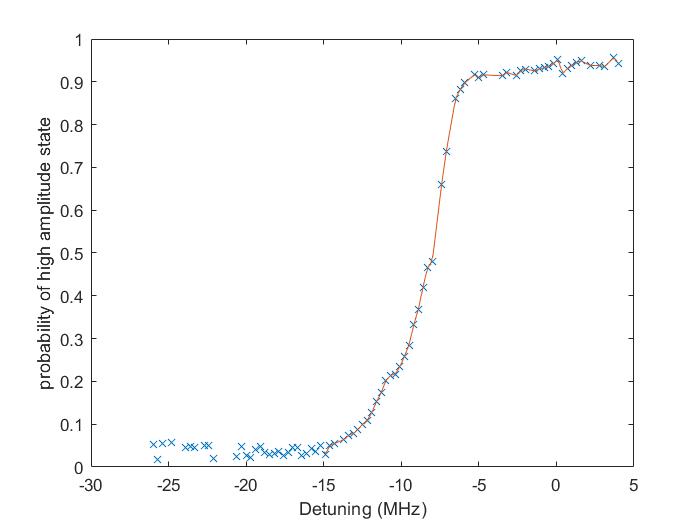

figure
plot(detuning_array, probability_best_180_360, 'x')
hold on
plot(detunings_array, interpolated_probability)
xlabel('Detuning (MHz)')
ylabel('probability of high amplitude state')

% interpolated_probability = 1 - interpolated_probability;

probability_array = repmat(interpolated_probability, size(detunings_array, 1), 1);
probability_array = repmat(probability_array, 1, 1, 3);
probability_array(:,:,3) = 1 - probability_array(:,:,3);
probability_array(:,:,2) = 0;
probability_array(amp_roots == 0) = 0;
probability_array_sum = sum(probability_array, 3);
probability_array_sum = repmat(probability_array_sum, 1, 1,3);
probability_array(probability_array >0 & probability_array_sum <1) = 1;
probability_array(probability_array >0 & probability_array_sum < 1) = 1;
probability_array_sum = sum(probability_array,3);
for i = 1: size(probability_array_sum,2)
    if probability_array_sum(1,i,1) == 0
        probability_array(1,i,3) = 1;
    end
end

s11_averaged = squeeze(sum(probability_array.*s11,3));

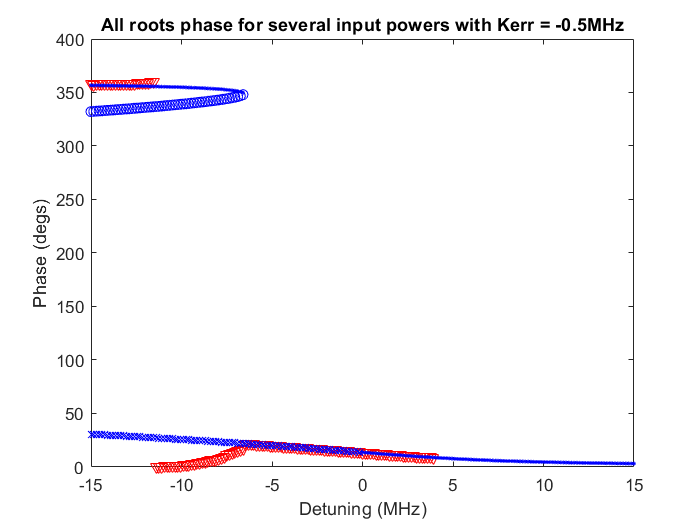

figure
    color_array = ['r', 'b', 'k', 'g', 'm'];
    i = 1;
    j = 1;
    while i<number_powers + 1
        detunings_array_averaged = detunings_array(i,:);
        s11_averaged_root_1_temp = s11_averaged(i,:);
        
        detunings_array_1 = detunings_array(i,:);
        s11_root_1_temp = s11(i,:,1);
        detunings_array_1 (s11_root_1_temp == 5) = [];
        s11_root_1_temp(s11_root_1_temp == 5) = [];
        
        detunings_array_2 = detunings_array(i,:);
        s11_root_2_temp = s11(i,:,2);
        detunings_array_2 (s11_root_2_temp == 5) = [];
        s11_root_2_temp(s11_root_2_temp == 5) = [];
        
        detunings_array_3 = detunings_array(i,:);
        s11_root_3_temp = s11(i,:,3);
        detunings_array_3 (s11_root_3_temp == 5) = [];
        s11_root_3_temp(s11_root_3_temp == 5) = [];
        root_1_color_prop = [color_array(j) 'v'];
        
        plot(detunings_array_averaged, wrapTo360(angle(s11_averaged_root_1_temp)*180/pi),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])
        hold on
        j = 2;
        root_1_color_prop = [color_array(j) 'x'];
        root_2_color_prop = [color_array(j) 'o'];
        root_3_color_prop = [color_array(j) '.'];
        plot(detunings_array_1, wrapTo360(angle(s11_root_1_temp)*180/pi),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])
        plot(detunings_array_2, wrapTo360(angle(s11_root_2_temp)*180/pi),root_2_color_prop)%,'o')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 2'])
        plot(detunings_array_3, wrapTo360(angle(s11_root_3_temp)*180/pi),root_3_color_prop)
        xlabel('Detuning (MHz)')
        ylabel('Phase (degs)')
        title(['All roots phase for several input powers with Kerr = ' num2str(kerr) 'MHz'])
        i = i + 20;
        j = j + 1;
    end
%     h = zeros(5,1);
%     h(1) = plot(nan, nan, 'r');hold on
%     h(2) = plot(nan, nan, 'b');
%     h(3) = plot(nan, nan, 'k');
%     h(4) = plot(nan, nan, 'g');
%     h(5) = plot(nan, nan, 'm');
%     legend (h, [num2str(power_input_in_dBm(1) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(21) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(41) + input_attenuation) 'dBm'],...
%         [num2str(power_input_in_dBm(61) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(input_attenuation) + input_attenuation) 'dBm'], 'stable root 1', 'unstable root', 'stable root 2')
     hold off

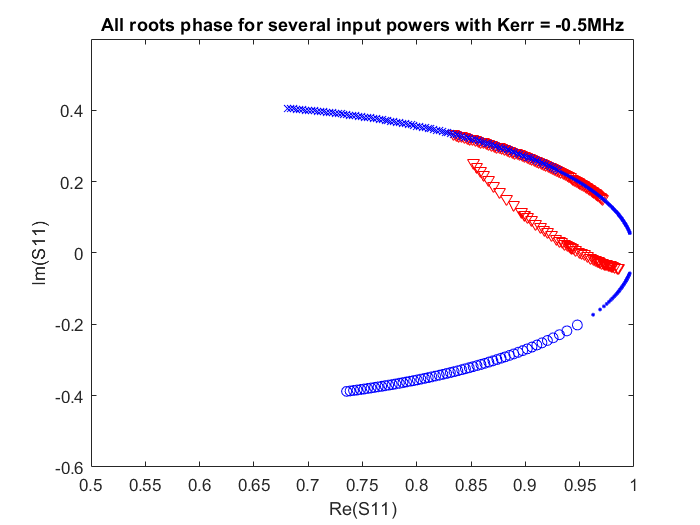

figure
    color_array = ['r', 'b', 'k', 'g', 'm'];
    i = 1;
    j = 1;
    while i<number_powers + 1
        detunings_array_averaged = detunings_array(i,:);
        s11_averaged_root_1_temp = s11_averaged(i,:);
        
        detunings_array_1 = detunings_array(i,:);
        s11_root_1_temp = s11(i,:,1);
        detunings_array_1 (s11_root_1_temp == 5) = [];
        s11_root_1_temp(s11_root_1_temp == 5) = [];
        
        detunings_array_2 = detunings_array(i,:);
        s11_root_2_temp = s11(i,:,2);
        detunings_array_2 (s11_root_2_temp == 5) = [];
        s11_root_2_temp(s11_root_2_temp == 5) = [];
        
        detunings_array_3 = detunings_array(i,:);
        s11_root_3_temp = s11(i,:,3);
        detunings_array_3 (s11_root_3_temp == 5) = [];
        s11_root_3_temp(s11_root_3_temp == 5) = [];
        root_1_color_prop = [color_array(j) 'v'];
        
        plot(real(s11_averaged_root_1_temp),imag(s11_averaged_root_1_temp),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])
        hold on
        j = 2;
        root_1_color_prop = [color_array(j) 'x'];
        root_2_color_prop = [color_array(j) 'o'];
        root_3_color_prop = [color_array(j) '.'];
        plot(real(s11_root_1_temp),imag(s11_root_1_temp),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])
        plot(real(s11_root_2_temp),imag(s11_root_2_temp),root_2_color_prop)%,'o')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 2'])
        plot(real(s11_root_3_temp),imag(s11_root_3_temp),root_3_color_prop)
        xlabel('Re(S11)')
        ylabel('Im(S11)')
        title(['All roots phase for several input powers with Kerr = ' num2str(kerr) 'MHz'])
        i = i + 20;
        j = j + 1;
    end
%     h = zeros(5,1);
%     h(1) = plot(nan, nan, 'r');hold on
%     h(2) = plot(nan, nan, 'b');
%     h(3) = plot(nan, nan, 'k');
%     h(4) = plot(nan, nan, 'g');
%     h(5) = plot(nan, nan, 'm');
%     legend (h, [num2str(power_input_in_dBm(1) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(21) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(41) + input_attenuation) 'dBm'],...
%         [num2str(power_input_in_dBm(61) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(input_attenuation) + input_attenuation) 'dBm'], 'stable root 1', 'unstable root', 'stable root 2')
     hold off
     axis([.5 1 -.6 .6])

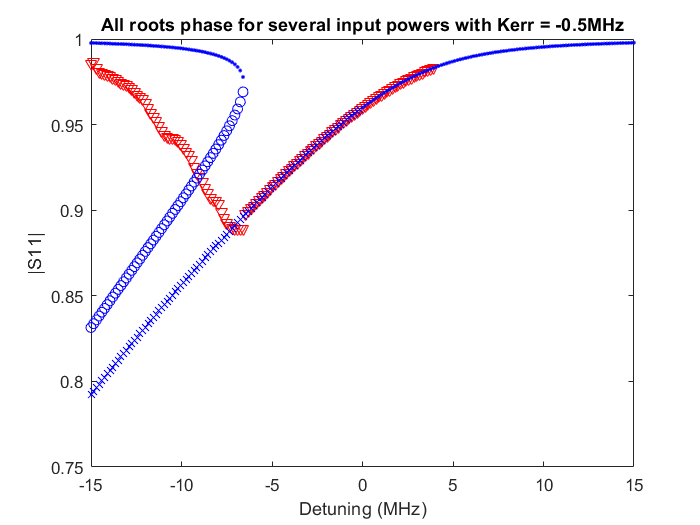

figure
    color_array = ['r', 'b', 'k', 'g', 'm'];
    i = 1;
    j = 1;
    while i<number_powers + 1
        detunings_array_averaged = detunings_array(i,:);
        s11_averaged_root_1_temp = s11_averaged(i,:);
        
        detunings_array_1 = detunings_array(i,:);
        s11_root_1_temp = s11(i,:,1);
        detunings_array_1 (s11_root_1_temp == 5) = [];
        s11_root_1_temp(s11_root_1_temp == 5) = [];
        
        detunings_array_2 = detunings_array(i,:);
        s11_root_2_temp = s11(i,:,2);
        detunings_array_2 (s11_root_2_temp == 5) = [];
        s11_root_2_temp(s11_root_2_temp == 5) = [];
        
        detunings_array_3 = detunings_array(i,:);
        s11_root_3_temp = s11(i,:,3);
        detunings_array_3 (s11_root_3_temp == 5) = [];
        s11_root_3_temp(s11_root_3_temp == 5) = [];
        root_1_color_prop = [color_array(j) 'v'];
        
        plot(detunings_array_averaged, abs(s11_averaged_root_1_temp),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])
        hold on
        j = 2;
        root_1_color_prop = [color_array(j) 'x'];
        root_2_color_prop = [color_array(j) 'o'];
        root_3_color_prop = [color_array(j) '.'];
        plot(detunings_array_1, abs(s11_root_1_temp),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 1'])
        plot(detunings_array_2, abs(s11_root_2_temp),root_2_color_prop)%,'o')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + input_attenuation) 'dBm, root 2'])
        plot(detunings_array_3, abs(s11_root_3_temp),root_3_color_prop)
        xlabel('Detuning (MHz)')
        ylabel('|S11|')
        title(['All roots phase for several input powers with Kerr = ' num2str(kerr) 'MHz'])
        i = i + 20;
        j = j + 1;
    end
%     h = zeros(5,1);
%     h(1) = plot(nan, nan, 'r');hold on
%     h(2) = plot(nan, nan, 'b');
%     h(3) = plot(nan, nan, 'k');
%     h(4) = plot(nan, nan, 'g');
%     h(5) = plot(nan, nan, 'm');
%     legend (h, [num2str(power_input_in_dBm(1) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(21) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(41) + input_attenuation) 'dBm'],...
%         [num2str(power_input_in_dBm(61) + input_attenuation) 'dBm'], [num2str(power_input_in_dBm(input_attenuation) + input_attenuation) 'dBm'], 'stable root 1', 'unstable root', 'stable root 2')
     hold off